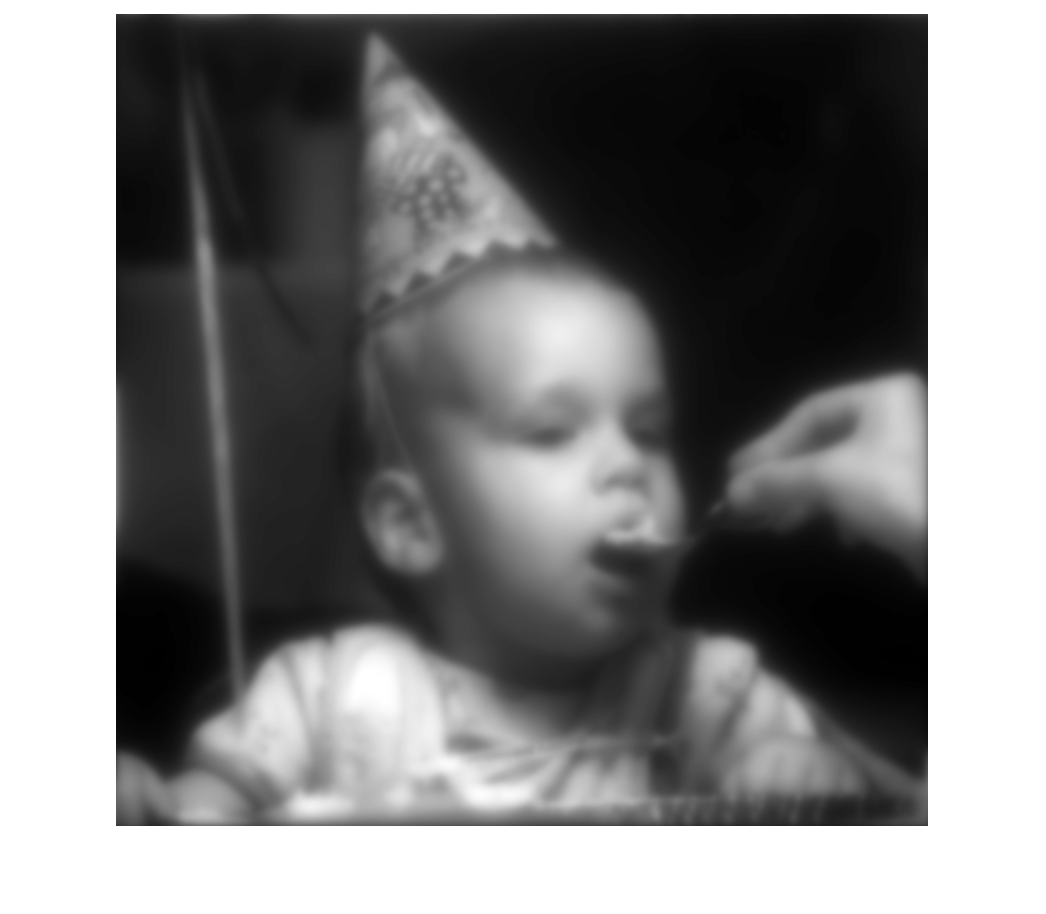

img = imread("../materials/child_degraded.tif");
[M, N] = size(img);
imshow(img, [])

H = load("../materials/H1&H2.mat").H1;

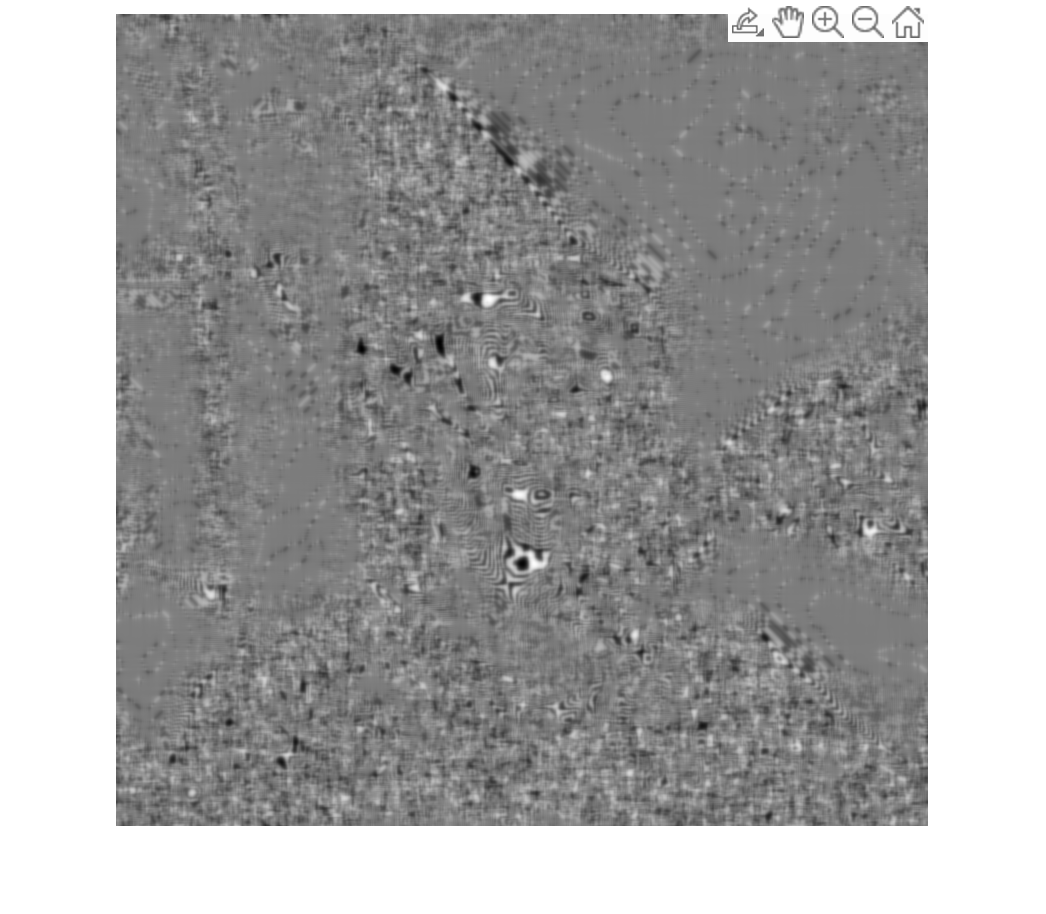

fft_img = fftshift(fft2(img));
r = 90; % cut-off radius
result_freq = fft_img ./ H; % full-inverse
result = real(ifft2(result_freq));
imshow(result, [])

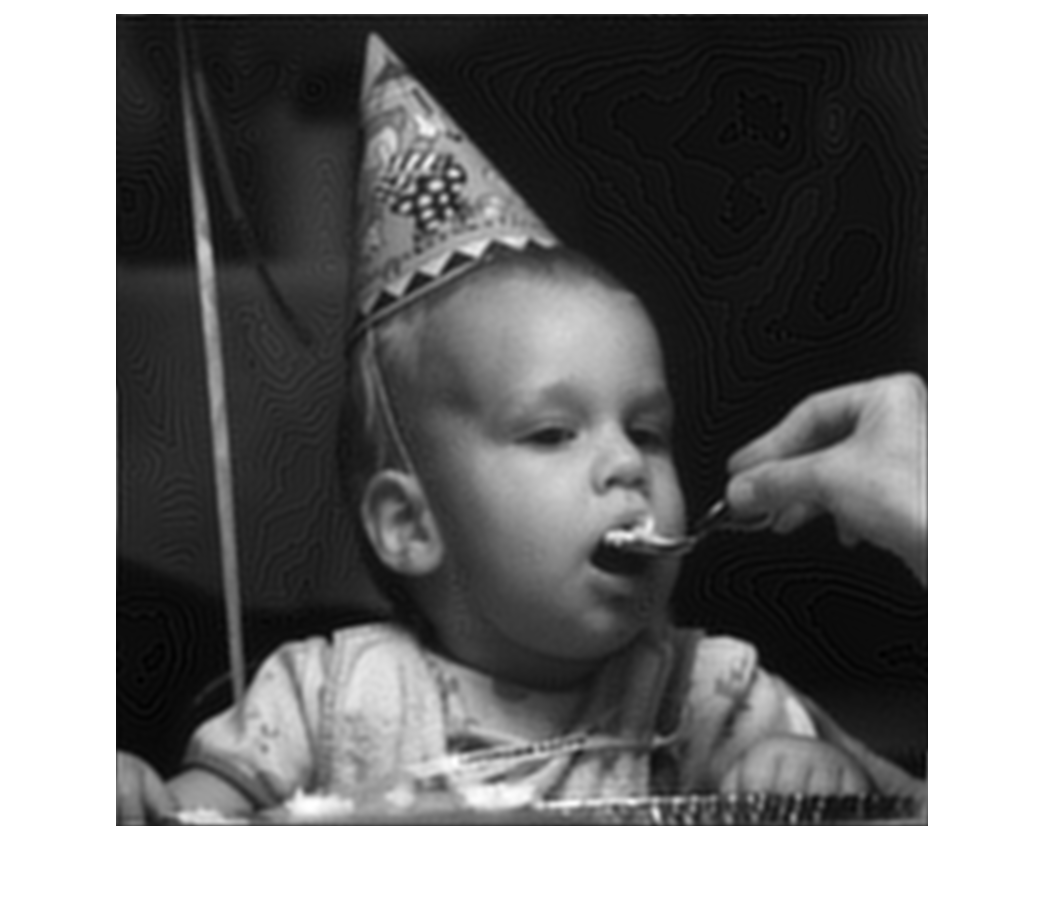

BW_filter = zeros(size(H)); % use Butterworth filter to perform "soft cut-off"
for x=1:M
    for y=1:N
        BW_filter(x, y) = 1 / (1 + (sqrt((x-M/2)^2+(y-N/2)^2)/r)^20);
    end
end
result_freq = fft_img ./ H .* BW_filter; % cut-off inverse
result = real(ifft2(result_freq));
result = result .* (-1).^((1:M)' + (1:N));
imshow(result, [])